# Getting Started with the Speedgoat Real-Time Driver-in-the-Loop Simulator

## Description

The Speedgoat Real-Time Driver-in-the-Loop Simulator demonstrates how to immerse the driver into compelling photorealistic 3D visualization environments in combination with the real-time simulation and high-fidelity capture of the vehicle dynamics, the behaviors of the tire and road surface. A gaming pedal and a steering wheel hardware are used for the driver input.

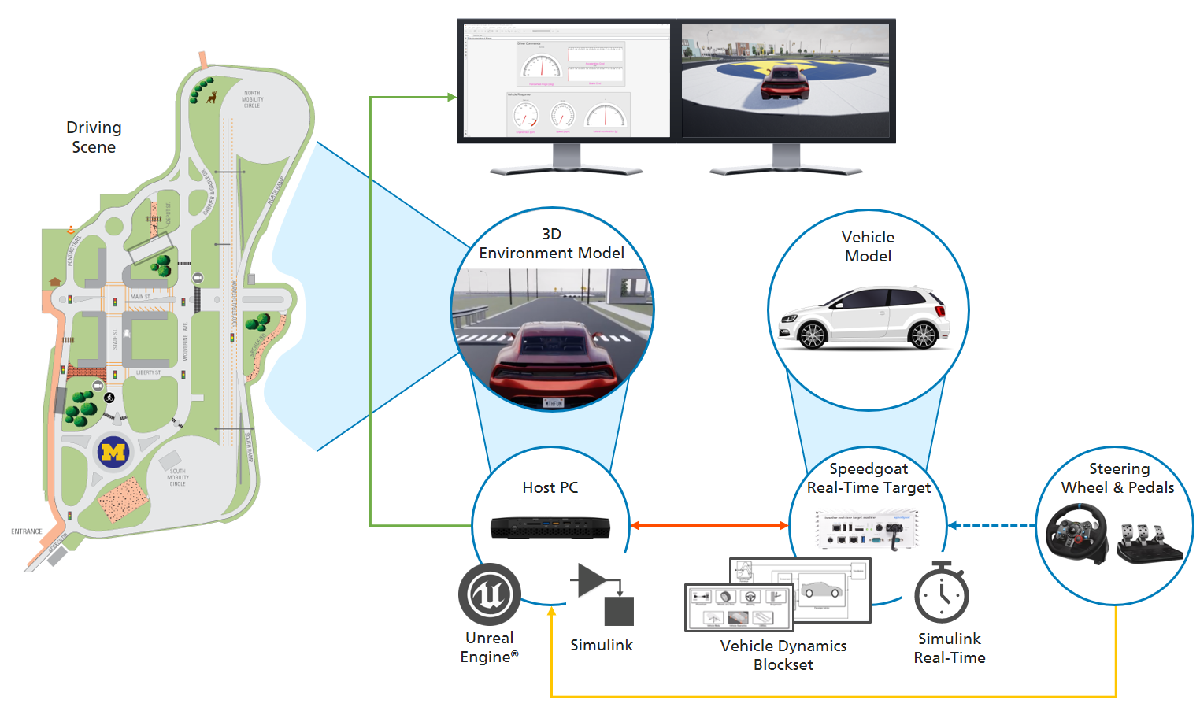    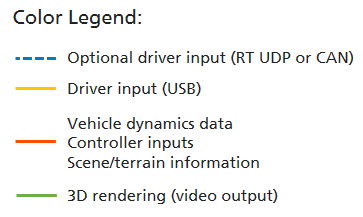

## System Requirements

Hardware:

- Host computer with powerful GPU (e.g. Intel NUC Hades Canyon NUC8i7HVK) and a screen

- Speedgoat real-time target machine (e.g. Baseline)

- Logitech G29 Driving Force Racing Wheel

Software:

- MATLAB R2019b

- Simulink

- Simulink Coder

- Simulink Real-Time

- Simulink 3D Animation

- Stateflow

- Powertrain Blockset

- Vehicle Dynamics Blockset

- Vehicle Dynamics Blockset Interface for Unreal Engine 4 Projects

- DSP System Toolbox

## Demo Setup

Load the MATLAB project by double-clicking the file "Real-Time Driver-in-the-Loop - Speedgoat.prj" in the MATLAB file browser.

Connect the real-time target machine to the host computer via Ethernet (host-target-link).

(The default IP addresses are stored in workspace variables set by the startup script: 192.168.7.1 for the target machine, and 192.168.7.2 for the host PC. If your configuration differs, set the variables accordingly.)

Connect and power the Logitech G29 steering wheel and pedals. The Logitech G29 steering wheel and pedals are connected to the Host PC via USB. There is a small switch in the steering wheel with two positions 'PS3' and 'PS4'. Select 'PS3'.

Install the Logitech G HUB driver software for the G29 steering wheel. The installer file is included in the support files folder. (If the installer is opened using the MATLAB command, the Windows security prompt may open in the background.)

 
system('support_files\software_packages\lghub_installer.exe');

It is also possible to connect the G29 steering wheel directly to the target computer via USB. The Logitech G HUB driver is not required in this case, but force feedback will not be available. To use this variant, change the "External Driver Input" variant subsystem in DriverInLoopSpeedgoat.slx to "G29 connected to target", and comment out the "Send Driver Commands" area in DriverInLoopGamingEngine.slx.

## Running the Demo

To build and deploy the real-time application on the target machine and open the host model, please make sure the host-target-link is established and click the '**Build and deploy real-time model**' project shortcut from the toolstrip, or run the following command:

 
DeployDemo

In case of any error when using the scrip, instead open the real-time model and build and deploy the model manually. Select "Build Application" from the Simulink Toolstrip, and afterwards select "Deploy to Target".

In the host model "DriverInLoopGamingEngine.slx", click the "Run" button in Simulink to run the demo. Execution on the target machine will be started automatically.

Use the G29 steering wheel to drive, and observe the instrument panels to see live information from the simulated vehicle.

In order to stop execution, press the "Stop" button in Simulink. Do not manually close the Unreal Engine window.

## Additional Info

Open the real-time model:

 
open_system('DriverInLoopSpeedgoat.slx')

Open the host PC model:

 
open_system('DriverInLoopGamingEngine.slx')

*Default IP configuration*

Real-time target machine: 192.168.7.1

Host PC: 192.168.7.2

## Release Notes

open README.md